# Part 1

clear
close all

x = sym( "x", "real" );
target_fun = sin( pi * x ) ^ 2;
domain = [-1, 1];
boundary_tol = 1e-2;
penalty = 1e2;
degree = 6;

[u, M, F, N, d] = ScalarProjection( "Monomial", target_fun, degree, domain, boundary_tol, penalty );
l2_error = ComputeL2Error( target_fun, simplify( u ), domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.08392805742559861$$

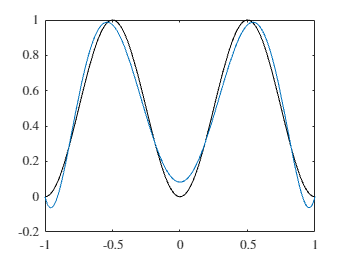


figure
hold on
fplot( target_fun, domain, color="k" )
fplot( u, domain, SeriesIndex=1 )

## Part 2

clear
close all

x = sym( "x", "real" );
target_fun = sin( pi * x ) ^ 2;
domain = [-1, 1];
boundary_tol = 1e-2;
penalty = 1e2;

degree = (0:12);
l2_error = zeros( size( degree ) );
for p = 1 : length( degree )
    u = ScalarProjection( "Monomial", target_fun, degree(p), domain, boundary_tol, penalty );
    l2_error(p) = double( vpa( simplify( ComputeL2Error( target_fun, simplify( u ), domain ), 16 ) ) );
end

figure
semilogy( degree, l2_error )